Lab Handout 1

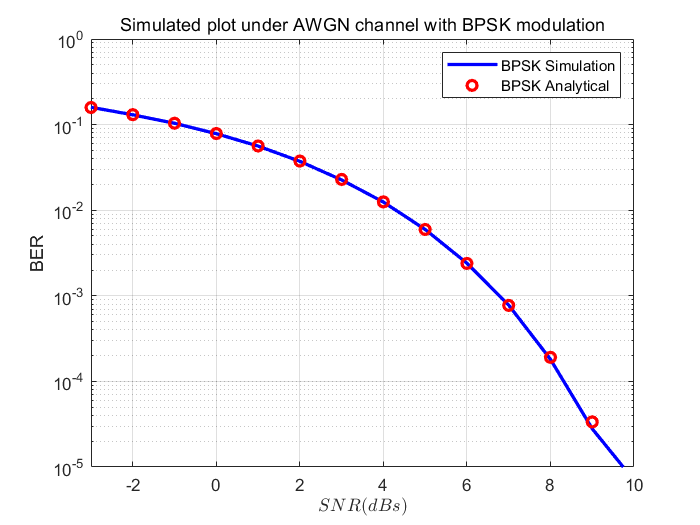

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% For BPSK

inputSignal = rand(1,N) > 0.5;
convertedSignal = 2*inputSignal - 1; % Converting 0,1 to -1,1

Eb_N0_db = (-3:10); % SNR range in decibels
Eb_N0_lin = power(10,Eb_N0_db/10);

for i = 1:length(Eb_N0_db)
    
    noise = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); % AWGN Noise
    addingNoise = power(10,-Eb_N0_db(i)/20) * noise; % noise normalizing
    
    % Adding noise to BPSK & QPSK modulated signal
    BPSKsig = convertedSignal + addingNoise;
    
    % To count error, 
    %    1) doing xor of input and recieved signal which will give 1 for error in input signal.
    %    2) count the ones in the xor array.
    
    % BPSK decoding & counting errors
    decBPSKSig = real(BPSKsig) > 0;
    BPSKdiffArr = xor(decBPSKSig,inputSignal) ;
    BPSKerr(i) = sum(BPSKdiffArr(:)==1);
    
end

BPSKber = BPSKerr/N; % Bit Error Rate
AWGNana = qfunc(sqrt(2*Eb_N0_lin));
close all;

figure;
semilogy(Eb_N0_db,BPSKber,"b-","LineWidth",2); % Plotting BPSK
hold on;
semilogy(Eb_N0_db,AWGNana,"ro","LineWidth",2);
hold off;
axis([-3 10 10^-5 1]);
grid("on");
legend('BPSK Simulation','BPSK Analytical');
title('Simulated plot under AWGN channel with BPSK modulation','FontWeight','Normal');
xlabel('$SNR (dBs)$','Interpreter','latex');
ylabel('BER');

Lab Handout 2

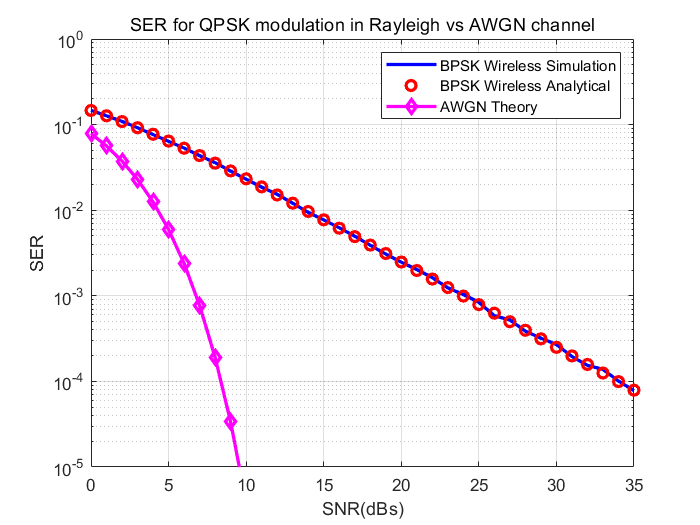

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

%BPSK signal generation

inputSig = rand(1,N) > 0.5;
convertedSig = 2*inputSig - 1; % Converting 0,1 to -1,1

Eb_N0_db = (0:35); % SNR range in decibels
Eb_N0_lin = power(10,Eb_N0_db/10);

for i = 1:length(Eb_N0_db)
    
    noise = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); % AWGN Noise
    addingNoise = power(10,-Eb_N0_db(i)/20) * noise; % to normalise the noise
    
    h = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); %For wireless system the channel shows random behaviour
    
    BPSKsigwireless = h.*convertedSig + addingNoise; % h will be multiplied with signal for wireless comm.
    BPSKsigwireless =  BPSKsigwireless./h;
    % To count error, 
    % 1) doing xor of input and recieved signal which will give 1 for error in input signal.
    % 2) count the ones in the xor array.   
   
    
    % BPSK decoding & counting errors for wireless channel
    decBPSKsigwireless = real(BPSKsigwireless) > 0;
    BPSKdiffArrwireless = xor(decBPSKsigwireless,inputSig);
    errwireless(i) = sum(BPSKdiffArrwireless(:)==1);
    
end

BPSKbersim = errwireless/N;
BPSKberana = 1/2*(1 - sqrt(Eb_N0_lin./(Eb_N0_lin + 1)));
AWGNana = qfunc(sqrt(2*Eb_N0_lin));


close all;

figure;
semilogy(Eb_N0_db,BPSKbersim,"b-","LineWidth",2); 
hold on
semilogy(Eb_N0_db,BPSKberana,"ro","LineWidth",2); 
hold on
semilogy(Eb_N0_db,AWGNana,"md-","LineWidth",2);
hold off;
grid("on");
axis([0 35 10^-5 1]);
legend('BPSK Wireless Simulation','BPSK Wireless Analytical','AWGN Theory');
title('SER for QPSK modulation in Rayleigh vs AWGN channel','FontWeight','Normal');
xlabel('SNR(dBs)');
ylabel('SER');

Lab Handout 3

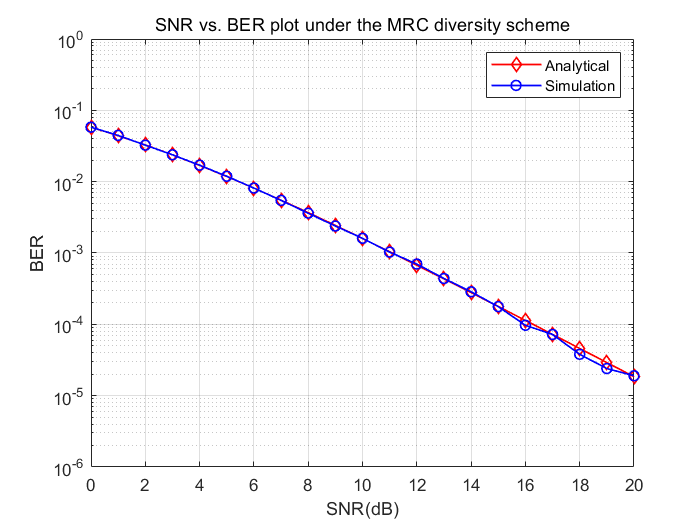

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% Range of SNR
Eb_N0_dB = 0:20;
Eb_N0_linear = power(10,Eb_N0_dB/10);

% Analytical BER for Rayleigh Wireless Channel for SISO
nRx_1_analytical = 0.5*(1-sqrt(Eb_N0_linear./(Eb_N0_linear + 1)));

mu = sqrt(Eb_N0_linear./(Eb_N0_linear + 1));

% Analytical BER for Wireless Channel for SIMO ( 1 transmitter & 2 reciever)
MRC_analytical = 1/4*(2 - 3*mu + mu.^3);

% Generating signal
bits = rand(1,N)>0;
signal = 2*bits - 1; % BPSK modulation

for i=1:length(Eb_N0_dB)
    
    % AWGN noice generation
    n1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    n2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % channel gain generation
    h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
    h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
  
    % normalising gain on basis of SNR value
    p = power(10,-Eb_N0_dB(i)/20);
    
    % Signal at the recieving end
    y1 = h1.*signal + p*n1;
    y2 = h2.*signal + p*n2;
    
    % Recieved signal for SIMO wireless ( 1 x 2 )
    MRC = conj(h1).*y1 + conj(h2).*y2;
    
    
    dMRC = real(MRC) >0;
    dfMRC = xor(dMRC,bits);
    BER_MRC(i)=sum(dfMRC(:)==1); % Error count for SIMO wireless (1x2)
    
end

% BER calculation
BER_MRC_simulation = BER_MRC/N;

% Plots
close all;
figure;
semilogy(Eb_N0_dB,MRC_analytical,'rd-',"LineWidth",1);
hold on
semilogy(Eb_N0_dB,BER_MRC_simulation,'bo-',"LineWidth",1);
hold off

grid("on");
axis([0 20 10^-6 1]);
legend('Analytical','Simulation');
title('SNR vs. BER plot under the MRC diversity scheme','FontWeight','Normal');
xlabel('SNR(dB)');
ylabel('BER');

Lab Handout 4

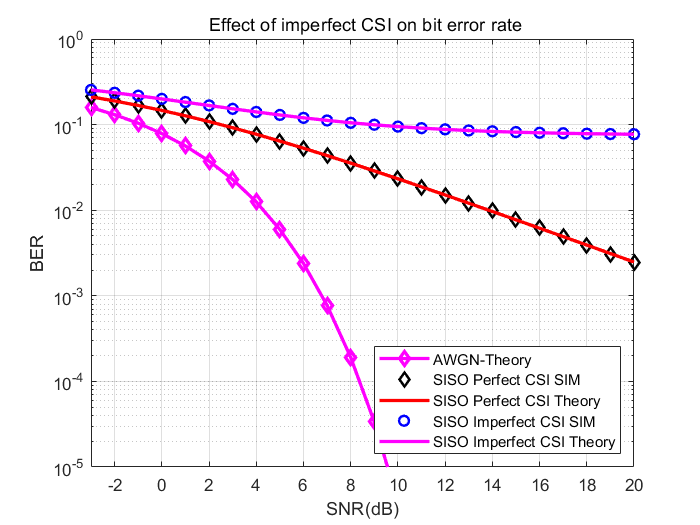

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% SNR Range
Eb_N0_dB = (-3:20);
% Conversion of dBs to linear scale
Eb_N0_linear = power(10,Eb_N0_dB/10);


mu = sqrt(Eb_N0_linear./(Eb_N0_linear + 1));

% ro1 is for the imperfect CSI
ro = 0.85;

SISO_AWGN = qfunc(sqrt(2*Eb_N0_linear));
SISO_perfect_CSI_theory = 1/2*(1-mu);
SISO_imperfect_CSI_theory = 1/2*(1-ro*mu);

% Generating input signal
input = rand(1,N)>0.5;
% BPSK modulation
signal = 2*input - 1;

for i=1:length(Eb_N0_dB)
    % AWGN Noise generation
    n = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
    
    % generating rayleigh random variable which is modelled for the channel coefficient
    hh = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    
    % generating the channel coefficient for the given value of ro = 1 (perfect csi) and generated h for Rx no. 1
    h =  ro*hh + sqrt(1-ro^2)*1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    

    p = power(10,(-Eb_N0_dB(i)/20));
    
    % recieved signal at reciever 1 along with the noise for ro = 0.9 (imperfect csi)
    y_timcsi = h.*signal + p*n;
    y_tpcsi = hh.*signal + p*n;
    
    % using the detection rule for SIMO Wireless system for both perfect & imperfect csi
    y_pcsi = conj(hh).*y_tpcsi;
    y_icsi = conj(hh).*y_timcsi; % here we are taking h1 & h2 as it is imperfect csi we don't know the values of h at reciever end
    
    % Applying MLD rule
    rsig_pcsi = real(y_pcsi) >= 0;
    % counting errors
    nerr_pcsi(i) = size(find([input-rsig_pcsi]), 2);
    
    % Applying MLD rule
    rsig_icsi = real(y_icsi) >= 0;
    % counting errors
    nerr_icsi(i) =  size(find([input-rsig_icsi]), 2);
    
end

% BER Calculation
ber_pcsi = nerr_pcsi/N;
ber_icsi = nerr_icsi/N;

% Plots
close all;
figure;
semilogy(Eb_N0_dB,SISO_AWGN,'md-',"LineWidth",2);
hold on
semilogy(Eb_N0_dB,ber_pcsi,'kd','LineWidth',1.5);
hold on
semilogy(Eb_N0_dB,SISO_perfect_CSI_theory,'r-',"LineWidth",2);
hold on
semilogy(Eb_N0_dB,ber_icsi,'bo','LineWidth',1.5);
hold on
semilogy(Eb_N0_dB,SISO_imperfect_CSI_theory,'m-',"LineWidth",2);
hold off
grid("on");
axis([-3 20 10^-5 1]);
LOC = "southeast";
legend('AWGN-Theory','SISO Perfect CSI SIM','SISO Perfect CSI Theory','SISO Imperfect CSI SIM','SISO Imperfect CSI Theory','Location',LOC);
title(' Effect of imperfect CSI on bit error rate','FontWeight','Normal');
xlabel('SNR(dB)');
ylabel('BER');

Lab Handout 5

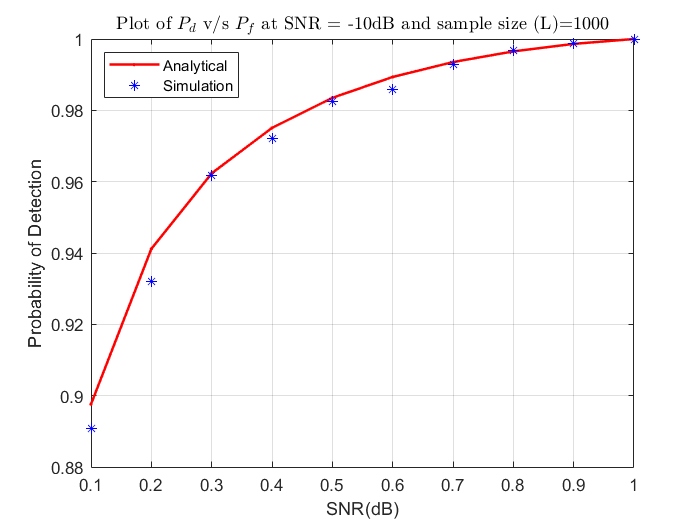

close all;
clc;

L = 1000; % u (Channel Length)
false_alarm_probability = 0.1:0.1:1; % Assumed probability of fasle alarm used for determining threshold value
threshold = (qfuncinv(false_alarm_probability)./sqrt(L))+1; % calculating threshold from Pf
snr_dB = -10; % range of SNR
snr_linear = power(10,snr_dB/10); % Converting value of SNR from dBs to linear

for i=1:length(false_alarm_probability)
    detection = 0; % initialising with 0
    for k=1:10000 % Number of Monte-Carlo Simulations
        noise = randn(1,L); % noise generation (Real AWGN Noise)
        signal = sqrt(snr_linear).*randn(1,L); % Input signal*gain
        rsignal = signal+noise; % received signal
        energy = power(abs(rsignal),2); % Energy Calculation
        test_statistic = sum(energy)/L; % Calculating the Test Statistic
        if(test_statistic >= threshold(i)) % using the definition of probability of detection
            detection = detection + 1;
        end
    end
    %detection
    Pd_simulation(i) = detection / k ;% calculating detection probability
end

numerator = L.*(threshold - (snr_linear+1));
denominator = sqrt(2*L*(snr_linear+1));
Pd_analytical = qfunc(numerator./denominator); % analytical formula for finding Pd

close all;
plot(false_alarm_probability,Pd_analytical,'r.-','LineWidth',1.5);
hold on
plot(false_alarm_probability,Pd_simulation,'b*');
axis([0.1 1 0.88 1])

LOC = "northwest";
legend('Analytical','Simulation','Location',LOC);
title('Plot of $P_d$ v/s $P_f$ at SNR = -10dB and sample size (L)=1000','Interpreter','latex','FontWeight','Normal');
xlabel('SNR(dB)');
ylabel('Probability of Detection');
grid on

Lab Handout 6 (A)

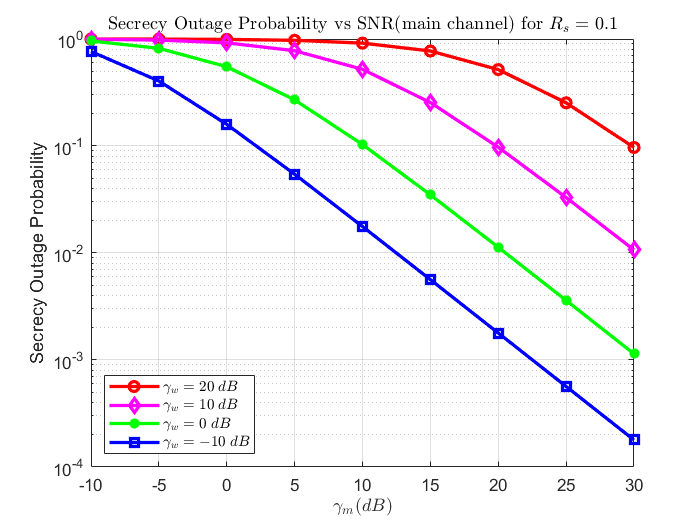

close all;
clc;

gamma_w = [20,10,0,-10];
gamma_w_linear = power(10,gamma_w/10);

gamma_m_dB = -10:5:30;
gamma_m = power(10,gamma_m_dB/10);
Rs = 0.1;
rs_power = power(2,Rs);

Pout = [];
for i=1:length(gamma_w)
    ratio = gamma_m./(gamma_m + rs_power.*gamma_w_linear(i));
    Poutage = 1 - ratio.*exp((1-rs_power)./gamma_m);
    Pout = [Pout ; Poutage];
end

close all;
figure;
semilogy(gamma_m_dB,Pout(1,:),'rO-','LineWidth',2);
hold on
semilogy(gamma_m_dB,Pout(2,:),'md-','LineWidth',2);
hold on
semilogy(gamma_m_dB,Pout(3,:),'g*-','LineWidth',2);
hold on
semilogy(gamma_m_dB,Pout(4,:),'bs-','LineWidth',2);
hold off

axis([-10 30 10^-4 1]);
grid on


legend('$\gamma_w = 20\; dB$','$\gamma_w = 10\; dB$','$\gamma_w = 0 \;dB$','$\gamma_w = -10 \;dB$','Interpreter','Latex','Location',"southwest");
title(' Secrecy Outage Probability vs SNR(main channel) for $R_s = 0.1$','FontWeight','Normal','Interpreter','Latex');
xlabel('$ \gamma_m(dB) $','Interpreter','Latex');
ylabel('Secrecy Outage Probability');

Lab Handout 6 (B)

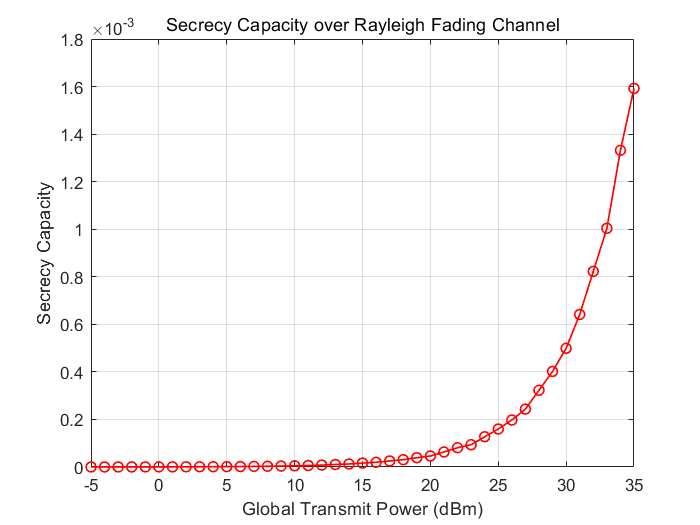

close all;
clc;

N = 1000;
Pt_dbm = -5:35;
Pt_watt = power(10,Pt_dbm/10)/1000;

Rs = 0.7;
alph = 3.5; % path loss exponent

d_sr = 500; % distance between source and relay
d_se = 1000*sqrt(1.25);

noise_power_dbm = -60;
noise_power = power(10,noise_power_dbm/10)/1000;

for i=1:length(Pt_watt)
    source_transmit_power = Pt_watt(i)/2;
    relay_transmit_power = Pt_watt(i)/2;

    channel_coeff_SR = sqrt(1/d_sr).*(randn(1,N) + 1i*randn(1,N));
    amplitude_SR = abs(channel_coeff_SR);
    CH_SR = power(amplitude_SR,2);

    SNR_R_linear = source_transmit_power*(1/power(d_sr,alph))*(CH_SR/noise_power);
    SNR_R_dB = 10*log10(SNR_R_linear);

    SNR_SR = mean(SNR_R_linear);
    SNR_SR_db =10*log10(SNR_SR);

    channel_coeff_SE = sqrt(1/d_se).*(randn (1,N) + 1i*randn (1,N));
    amplitude_SE = abs(channel_coeff_SE);
    CH_SE = power(amplitude_SE,2);

    SNR_E_linear = source_transmit_power*(1/power(d_se,alph))*(CH_SE/noise_power);
    SNR_E_dB = 10*log10(SNR_E_linear);

    SNR_SE = mean(SNR_E_linear);
    SNR_SE_db =10*log10(SNR_SE);

    Cs(i) = 1/2*log2((1+SNR_SR)./(1+SNR_SE));
end

close all;
figure;
plot(Pt_dbm,Cs,'ro-','LineWidth',1);
axis([-5 35 0 0.0018]);
grid on

title('Secrecy Capacity over Rayleigh Fading Channel','FontWeight','Normal');
xlabel('Global Transmit Power (dBm)');
ylabel('Secrecy Capacity');

Lab Handout 6 (C)

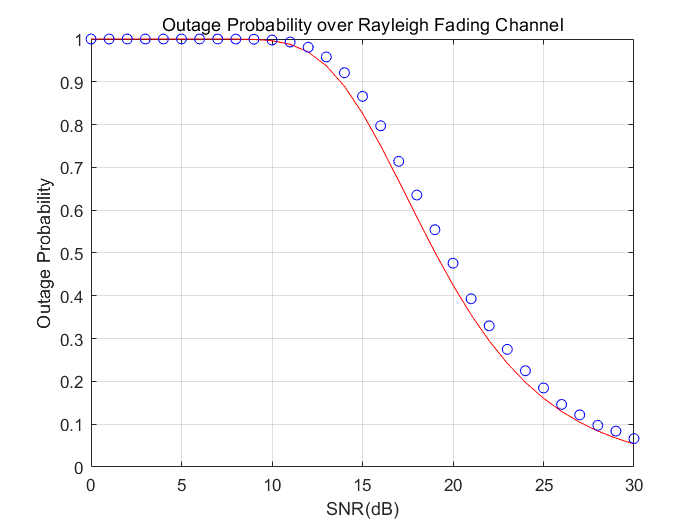

close all;
clc;

snr_db = 0:30;
snr = power(10,snr_db/10);

no_of_bits = power(2,8);
N = 10000;

BER_threshold = 10^-4;
SNR_threshold = 55.3536;


for i = 1:length(snr)
    error_block = 0;
    sig = sqrt(1/(2*snr(i)));
    for j = 1:N
        message = rand(1,no_of_bits) > 0.5;
        trans_bits = 2*message - 1;
        h = 1/sqrt(2)*(randn(1,no_of_bits) + 1i*randn(1,no_of_bits));
        noise = sig*(randn(1,no_of_bits)+ 1i*randn(1,no_of_bits));

        rec_bits = h.*trans_bits + noise;
        dec_bits = conj(h).*rec_bits;
        decoded_bits = real(dec_bits) >= 0;
        xored_bits = xor(decoded_bits,message);
        no_of_error = sum(xored_bits(:)==1);
        block_BER = no_of_error / no_of_bits;
        if(block_BER > BER_threshold)
            error_block = error_block + 1;
        end
    end
    ratio_errb(i) = error_block/N;
    OP_th(i) = 1 - exp(-SNR_threshold./snr(i));
end

close all;
figure;
plot(snr_db,OP_th,'r-');
hold on
plot(snr_db,ratio_errb,'bo');
hold off

grid on
axis([0 30 0 1]);

title('Outage Probability over Rayleigh Fading Channel','FontWeight','Normal');
xlabel('SNR(dB)');
ylabel('Outage Probability');

Lab Handout 7

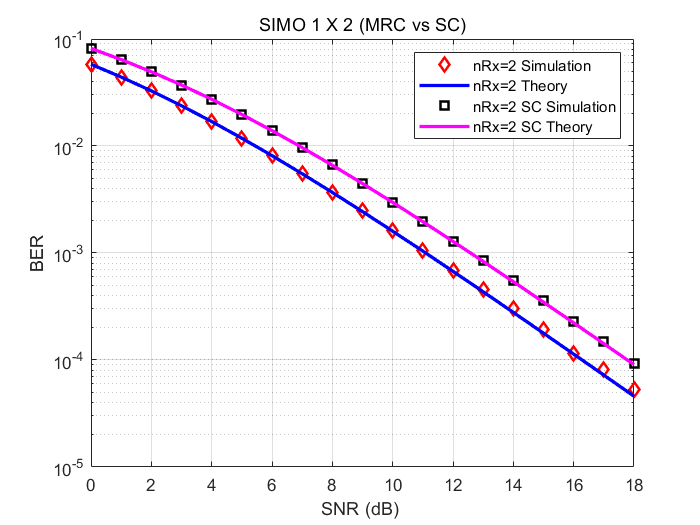

close all;
clc;

% Number of bits to be transmitted
N = 10^6;

% Range of SNR
Eb_N0_dB = 0:18;
Eb_N0_linear = power(10,Eb_N0_dB/10);

mu = sqrt(Eb_N0_linear./(Eb_N0_linear+1));

% Generating signal
bits = rand(1,N)>0;
signal = 2*bits - 1; % BPSK modulation

% AWGN noice generation
n1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
n2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));

% channel gain generation
h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)); 
h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));

for i=1:length(Eb_N0_dB)
    
    % normalising gain on basis of SNR value
    p = power(10,-Eb_N0_dB(i)/20);
    
    % Signal at the recieving end
    y1 = h1.*signal + p*n1;
    y2 = h2.*signal + p*n2;
    
    % Recieved signal for SIMO wireless ( 1 x 2)
    rnRx_2 = conj(h1).*y1 + conj(h2).*y2;
    
    % Channel Power
    H1 = h1.*conj(h1);
    H2 = h2.*conj(h2);
    
    % Antenna Detection Rule for 1x2 SIMO Selection Combining
    for j=1:N
        % Calculating the max energy for SC 1x2
        max_energy_rx2 = max([H1(j),H2(j)]);
        
        % Antenna Selection rule for 1x3 SC
        if(max_energy_rx2 == H1(j))
            channel_gain_rx2(j) = h1(j);
            recieved_signal_rx2(j) = y1(j);
        else
            channel_gain_rx2(j) = h2(j);
            recieved_signal_rx2(j) = y2(j);
        end
    end    
    
    % Using the detection rule for SIMO SC after applying the antenna rule
    dec_rx2 = conj(channel_gain_rx2).*recieved_signal_rx2;
    
    % The following code decodes the signal by taking the real part and
    % counting the error bits. for SC
    
    dbnRx_2_SC = real(dec_rx2) >0;
    dfnRx_2_SC = xor(dbnRx_2_SC,bits);
    BER_nRx_2_SC(i)=sum(dfnRx_2_SC(:)==1);
    
    % The following code decodes the signal by taking the real part and
    % counting the error bits for MRC.
    
    dbnRx_2 = real(rnRx_2) >0;
    dfnRx_2 = xor(dbnRx_2,bits);
    BER_nRx_2(i)=sum(dfnRx_2(:)==1); % Error count for SIMO wireless (1x2)
    
end

% BER Calculation
BER_nRx_2_simulation = BER_nRx_2/N;
BER_nRx_2_SC_simulation = BER_nRx_2_SC/N;
BER_nRx_2_theory = 1/4*(2-3*mu + power(mu,3));
BER_nRx_2_SC_theory = 1/2 - mu + 1/2*sqrt(Eb_N0_linear./(Eb_N0_linear+2));

% Plots
close all;
figure;
semilogy(Eb_N0_dB,BER_nRx_2_simulation,'rd','LineWidth',1.5);
hold on
semilogy(Eb_N0_dB,BER_nRx_2_theory,'b-','LineWidth',2);
hold on
semilogy(Eb_N0_dB,BER_nRx_2_SC_simulation,'ks','LineWidth',1.5);
hold on
semilogy(Eb_N0_dB,BER_nRx_2_SC_theory,'m-','LineWidth',2);
hold off
grid on
axis([0 18 10^-5 10^-1]);
legend('nRx=2 Simulation','nRx=2 Theory','nRx=2 SC Simulation','nRx=2 SC Theory');
title('SIMO 1 X 2 (MRC vs SC)','FontWeight','Normal');
xlabel('SNR (dB) ');
ylabel('BER');

Lab Handout 8

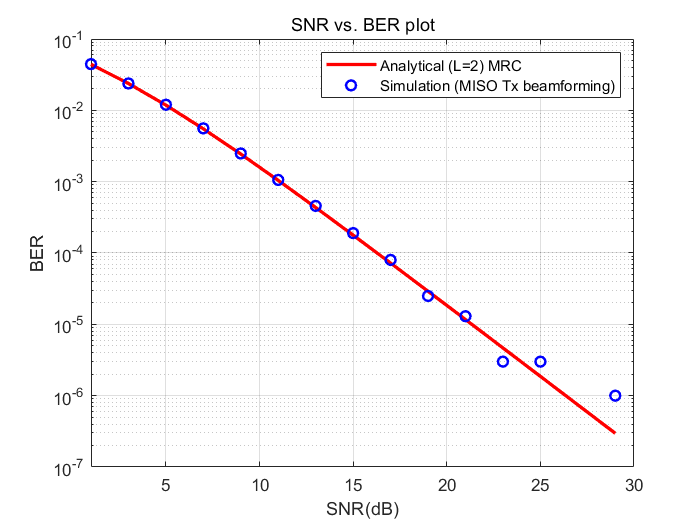

close all;
clc;
rng('shuffle');

SNR_db = 1:2:30;
SNR = power(10,SNR_db/10);

mu = sqrt(SNR./(SNR+1));
MRC_L2_Theory = 1/4*(2 - 3*mu + power(mu,3));

N = 10^6;

bits = rand(1,N)>0;
signal = 2*bits - 1;

for L=1:length(SNR_db)
   h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
   h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
   
   p = sqrt(1/SNR(L));
   noise = (1/sqrt(2)*(randn(1,N) + 1i*randn(1,N)))*p;
   mod_h = sqrt(power(abs(h1),2) + power(abs(h2),2));
   x1 = (conj(h1).*signal)./mod_h;
   x2 = (conj(h2).*signal)./mod_h;
   
   y = h1.*x1 + h2.*x2 + noise;
   
   real_dec_y = real(y) >= 0;
   diff_bits = xor(real_dec_y,bits);
   error(L) = sum(diff_bits(:)==1);

end

BER_TB = error/N;

close all;
figure;
semilogy(SNR_db,MRC_L2_Theory,'r-','LineWidth',2);
hold on
semilogy(SNR_db,BER_TB,'bo','LineWidth',1.5);
hold off
axis([1 30 10^-7 10^-1]);
grid on

legend('Analytical (L=2) MRC','Simulation (MISO Tx beamforming)');
title('SNR vs. BER plot','FontWeight','Normal');
xlabel('SNR(dB)');
ylabel('BER');

OFDM Practice BER

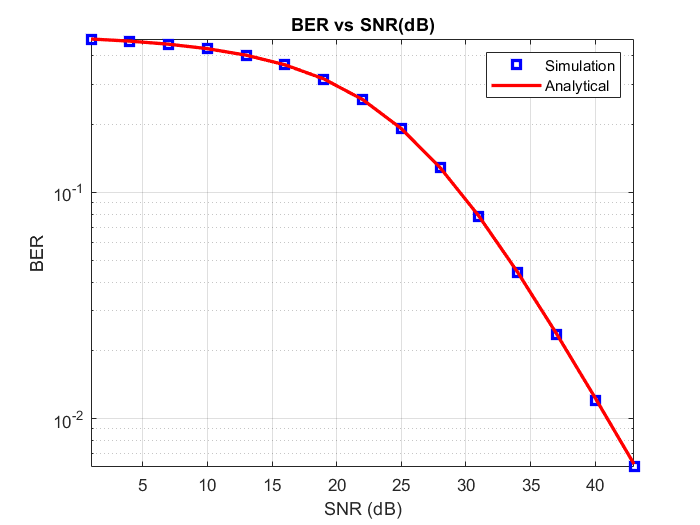

close all;
clc;
rng('shuffle');

SNR_db = 1:3:45;
number_of_subcarrier = 512;
Ncp = round(number_of_subcarrier/10);
number_of_blocks = 10000;
number_of_taps = 2;
BER = zeros(size(SNR_db));
SNR = zeros(size(SNR_db));

for L=1:number_of_blocks
    bits = randi([0,1],[1,number_of_subcarrier]);
    h = 1/sqrt(2)*(randn(1,number_of_taps) + 1i*randn(1,number_of_taps));
    Hfreq = fft(h,number_of_subcarrier);
    channel_noise = (randn(1,number_of_taps+number_of_subcarrier+Ncp-1) + 1i*randn(1,number_of_taps+number_of_subcarrier+Ncp-1));
    
    for K=1:length(SNR_db)
        SNR(K) = power(10,SNR_db(K)/10);
        loaded_bits = sqrt(SNR(K))*(2*bits-1);
        Tx_samples = ifft(loaded_bits);
        Tx_samples_cp = [Tx_samples(number_of_subcarrier-Ncp+1:number_of_subcarrier),Tx_samples];
        Rx_bits = conv(h,Tx_samples_cp) + channel_noise;
        Rx_bits_without_cp = Rx_bits(Ncp+1:Ncp+number_of_subcarrier);
        Rx_bits_fft = fft(Rx_bits_without_cp,number_of_subcarrier);
        processed_bits = Rx_bits_fft./Hfreq;
        decoded_bits = real(processed_bits) >= 0;
        BER(K) = BER(K) + sum(decoded_bits ~= bits);
    end
end

eSNR = number_of_taps*SNR/number_of_subcarrier;
BER = BER/(number_of_blocks*number_of_subcarrier);

close all;
figure;
semilogy(SNR_db,BER,'b s','LineWidth',2);
hold on
semilogy(SNR_db,1/2*(1-sqrt(eSNR./(2+eSNR))),'r-','LineWidth',2);
hold off
grid on
axis tight

legend('Simulation','Analytical');
xlabel('SNR (dB)');
ylabel('BER');
title('BER vs SNR(dB)');

Spatial Correlation

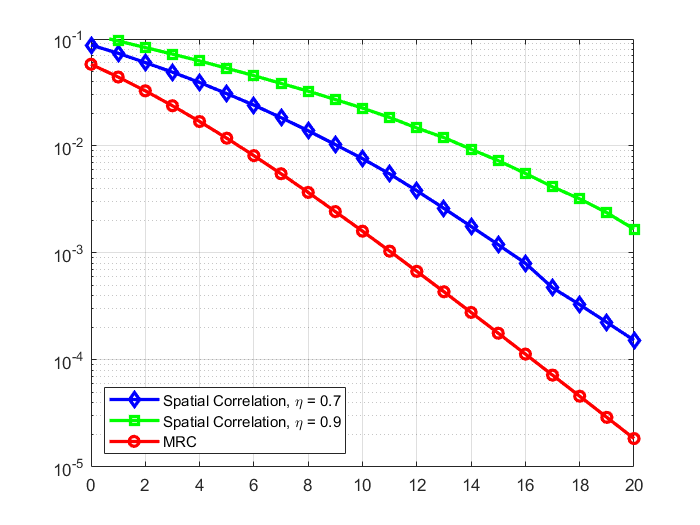

close all;
clc;

SNR_db = 0:20;
SNR_lin = power(10,SNR_db/10);

N = power(10,6);

mu = sqrt(SNR_lin./(1+SNR_lin));
SIMO_MRC = 1/4*(2 - 3*mu + power(mu,3));

sig = rand(1,N) > 0.5;
x = 2*sig - 1;

eta = 0.7;
eta_2 = 0.9;


for i=1:length(SNR_lin)
    h1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    h2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    noise_1 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    noise_2 = 1/sqrt(2)*(randn(1,N) + 1i*randn(1,N));
    p = power(10,-SNR_db(i)/20);
    
    y1 = (h1 + eta*h2).*x + noise_1*p;
    y2 = (eta*h1 + h2).*x + noise_2*p;
    
    y1_2 = (h1 + eta_2*h2).*x + noise_1*p;
    y2_2 = (eta_2*h1 + h2).*x + noise_2*p;
    
    y = conj(h1).*y1 + conj(h2).*y2;
    y_2 = conj(h1).*y1_2 + conj(h2).*y2_2;
    
    decoded_y = real(y)>=0;
    xor_y = xor(decoded_y,sig);
    ber_sc(i) = sum(xor_y(:)==1);
    
    decoded_y_2 = real(y_2)>=0;
    xor_y_2 = xor(decoded_y_2,sig);
    ber_sc_2(i) = sum(xor_y_2(:)==1);
    
end
ber_sc = ber_sc/N;
ber_sc_2 = ber_sc_2/N;

%mu_1 = sqrt(((1+eta)*SNR_lin)./(1 + (1+eta)*SNR_lin));
%mu_2 = sqrt(((1-eta)*SNR_lin)./(1 + (1-eta)*SNR_lin));
%ber_ana = 1/4*(((1+eta)*(1-mu_1)) - ((1-eta)*(1 - mu_2)));

%mu_1_2 = sqrt(((1+eta_2)*SNR_lin)./(1 + (1+eta_2)*SNR_lin));
%mu_2_2 = sqrt(((1-eta_2)*SNR_lin)./(1 + (1-eta_2)*SNR_lin));
%ber_ana_2 = 1/4*(((1+eta_2)*(1-mu_1_2)) - ((1-eta_2)*(1 - mu_2_2)));

close all;
figure;
semilogy(SNR_db,ber_sc,'bd-','LineWidth',2);
hold on
semilogy(SNR_db,ber_sc_2,'gs-','LineWidth',2);
hold on
semilogy(SNR_db,SIMO_MRC,'ro-','LineWidth',2);
hold off
grid on
axis([0 20 10^-5 10^-1]);
legend("Spatial Correlation, \eta = 0.7","Spatial Correlation, \eta = 0.9","MRC",'Location','southwest');